Code for performing non-linear regression on the mean mRNA count induction curve from experimental data sets.

Dataset 1 - Yeast, osmotic stress

%Import data (mRNA count and time)
%e.g. CTT1, Experiment 1, nuclear and cytoplasmic mRNA counts

mRNAcount_CTT1_EXP1_N = [0.013895907; 0.016260163; 0.013281682; 0.099388379; 0.391518132; 0.767029193] %nuclear counts

mRNAcount_CTT1_EXP1_N =     0.0139
    0.0163
    0.0133
    0.0994
    0.3915
    0.7670


times_CTT1_EXP1_N = [0; 1; 2; 4; 6; 8] %nuclear count times (minutes)

times_CTT1_EXP1_N =      0
     1
     2
     4
     6
     8



mRNAcount_CTT1_EXP1_C = [0.570742799; 0.383920506; 0.389042612; 0.967380224; 5.353411186; 17.58614768] %cytoplasmic counts

mRNAcount_CTT1_EXP1_C =     0.5707
    0.3839
    0.3890
    0.9674
    5.3534
   17.5861


times_CTT1_EXP1_C = [0; 1; 2; 4; 6; 8] %cytoplasmic count times (minutes)

times_CTT1_EXP1_C =      0
     1
     2
     4
     6
     8



%specify the form of the power law model
%coefficients to estimate:
    %c(1) = prefactor
    %c(2) = exponent
model_fun1 = @(c,t)(c(1)*t.^(c(2)));

%non-linear regression - nuclear counts
c0 = [0.001, 2]; %initial c(1) and c(2) estimates to begin the nlinfit algorithm
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(times_CTT1_EXP1_N, mRNAcount_CTT1_EXP1_N, model_fun1, c0);
prefactor_CTT1_EXP1_N = beta(1)

prefactor_CTT1_EXP1_N = 0.0035

exponent_CTT1_EXP1_N = beta(2)

exponent_CTT1_EXP1_N = 2.5995


%construct a table object (with mRNA counts and times) to estimate standard
%error in coefficient estimates
tbl_CTT1_EXP1_N = table(times_CTT1_EXP1_N, mRNAcount_CTT1_EXP1_N);
mdl_CTT1_EXP1_N = fitnlm(tbl_CTT1_EXP1_N, model_fun1, [beta(1), beta(2)])

mdl_CTT1_EXP1_N = Nonlinear regression model:
    mRNAcount_CTT1_EXP1_N ~ (c1*t^(c2))

Estimated Coefficients:
          Estimate        SE        tStat       pValue  
          _________    _________    ______    __________

    c1    0.0034772    0.0011916     2.918      0.043331
    c2       2.5995      0.16986    15.303    0.00010636


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.0218
R-Squared: 0.996,  Adjusted R-Squared 0.995
F-statistic vs. zero model: 790, p-value = 6.37e-06


%non-linear regression - cytoplasmic counts
c0 = [0.01, 5]; %initial c(1) and c(2) estimates to begin the nlinfit algorithm
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(times_CTT1_EXP1_C, mRNAcount_CTT1_EXP1_C, model_fun1, c0);
prefactor_CTT1_EXP1_C = beta(1)

prefactor_CTT1_EXP1_C = 0.0033

exponent_CTT1_EXP1_C = beta(2)

exponent_CTT1_EXP1_C = 4.1322


%construct a table object (with mRNA counts and times) to estimate standard
%error in coefficient estimates
tbl_CTT1_EXP1_C = table(times_CTT1_EXP1_C, mRNAcount_CTT1_EXP1_C);
mdl_CTT1_EXP1_C = fitnlm(tbl_CTT1_EXP1_C, model_fun1, [beta(1), beta(2)])

mdl_CTT1_EXP1_C = Nonlinear regression model:
    mRNAcount_CTT1_EXP1_C ~ (c1*t^(c2))

Estimated Coefficients:
          Estimate        SE        tStat       pValue  
          _________    _________    ______    __________

    c1    0.0032612    0.0015771    2.0678       0.10749
    c2       4.1322      0.23533    17.559    6.1776e-05


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.381
R-Squared: 0.998,  Adjusted R-Squared 0.997
F-statistic vs. zero model: 1.16e+03, p-value = 2.94e-06

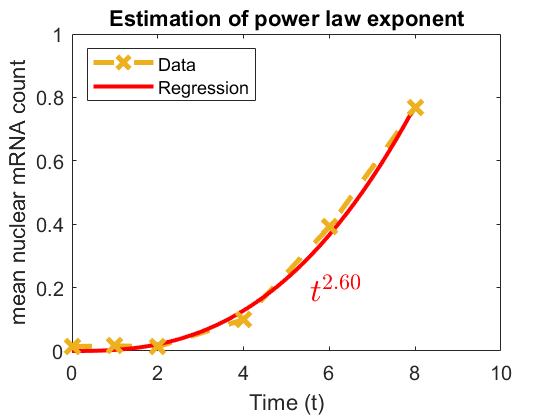


%Compute power law regression curve using estimated prefactor and exponent
time_range1 = 0:0.2:8; %time range to compute regression over
%nuclear
reg_CTT1_EXP1_N = prefactor_CTT1_EXP1_N.*(time_range1.^exponent_CTT1_EXP1_N);
%cytoplasmic
reg_CTT1_EXP1_C = prefactor_CTT1_EXP1_C.*(time_range1.^exponent_CTT1_EXP1_C);

%Plot data and regression results

%nuclear
fig_N = figure;
%data (lines)
p1_N = plot(times_CTT1_EXP1_N, mRNAcount_CTT1_EXP1_N, '--', 'Color', "#EDB120", LineWidth=2.5, Marker="x", MarkerSize=10);
hold on
%regression
p2_N = plot(time_range1, reg_CTT1_EXP1_N, 'r-', 'LineWidth', 2);
hold on
%data (points)
s1_N = scatter(times_CTT1_EXP1_N, mRNAcount_CTT1_EXP1_N, 6, 'x', 'ColorVariable', "#EDB120", 'LineWidth', 10);
%plot features
legend('Data', 'Regression', 'Location', 'northwest')
xlabel('Time (t)')
ylabel('mean nuclear mRNA count')
title('Estimation of power law exponent')
xlim([0, 10])
ylim([0, 1])
%add text for exponent
annotation(fig_N,'textbox',...
    [0.541666666666666 0.29536711235484 0.0416666666666668 0.0583613771289075],...
    'Color',[1, 0, 0],...
    'String',{'$t^{2.60}$'},...
    'Interpreter','latex',...
    'FontSize',16,...
    'FitBoxToText','off',...
    'EdgeColor','none');

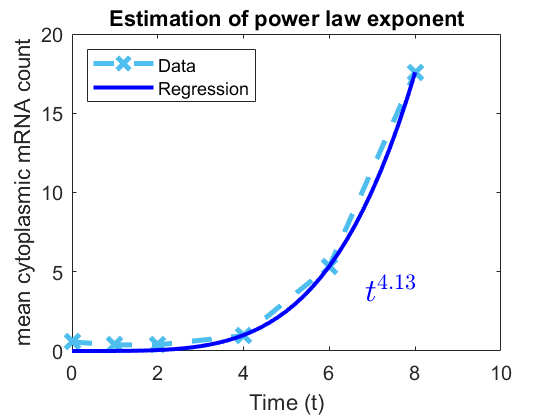


%cytoplasmic
fig_C = figure;
%data (lines)
p1_C = plot(times_CTT1_EXP1_C, mRNAcount_CTT1_EXP1_C, '--', 'Color', "#4DBEEE", LineWidth=2.5, Marker="x", MarkerSize=10);
hold on
%regression
p2_C = plot(time_range1, reg_CTT1_EXP1_C, 'b-', 'LineWidth', 2);
hold on
%data (points)
%s1_C = scatter(times_CTT1_EXP1_C, mRNAcount_CTT1_EXP1_C, 6, 'x', 'ColorVariable', "#4DBEEE", 'LineWidth', 10);
%plot features
legend('Data', 'Regression', 'Location', 'northwest')
xlabel('Time (t)')
ylabel('mean cytoplasmic mRNA count')
title('Estimation of power law exponent')
xlim([0, 10])
ylim([0, 20])
%add text for exponent
annotation(fig_C,'textbox',...
    [0.641666666666666 0.29536711235484 0.0416666666666668 0.0583613771289075],...
    'Color',[0, 0, 1],...
    'String',{'$t^{4.13}$'},...
    'Interpreter','latex',...
    'FontSize',16,...
    'FitBoxToText','off',...
    'EdgeColor','none');

Dataset 2 - Mouse, inflammatory response

%Import data (mRNA count and time)
%e.g. Fibroblast, mRNA, Icam1

mRNAcount_Fib_mRNA_Icam1 = [0; 0; 0; 2.168674699; 6.144578313; 22.40963855] %mRNA counts

mRNAcount_Fib_mRNA_Icam1 =          0
         0
         0
    2.1687
    6.1446
   22.4096


times_Fib_mRNA_Icam1 = [0; 0.175675676; 0.337837838; 0.391891892; 0.5; 0.662162162] %times (hours)

times_Fib_mRNA_Icam1 =          0
    0.1757
    0.3378
    0.3919
    0.5000
    0.6622



%specify the form of the power law model
%coefficients to estimate:
    %c(1) = prefactor
    %c(2) = exponent
model_fun1 = @(c,t)(c(1)*t.^(c(2)));

%non-linear regression
c0 = [100, 4]; %initial c(1) and c(2) estimates to begin the nlinfit algorithm
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(times_Fib_mRNA_Icam1, mRNAcount_Fib_mRNA_Icam1, model_fun1, c0);
prefactor_Fib_mRNA_Icam1 = beta(1)

prefactor_Fib_mRNA_Icam1 = 157.1846

exponent_Fib_mRNA_Icam1 = beta(2)

exponent_Fib_mRNA_Icam1 = 4.7215


%construct a table object (with mRNA counts and times) to estimate standard
%error in coefficient estimates
tbl_Fib_mRNA_Icam1 = table(times_Fib_mRNA_Icam1, mRNAcount_Fib_mRNA_Icam1);
mdl_Fib_mRNA_Icam1 = fitnlm(tbl_Fib_mRNA_Icam1, model_fun1, [beta(1), beta(2)])

mdl_Fib_mRNA_Icam1 = Nonlinear regression model:
    mRNAcount_Fib_mRNA_Icam1 ~ (c1*t^(c2))

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    c1     157.18      17.594    8.9341    0.00086801
    c2     4.7215     0.25252    18.698    4.8169e-05


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 0.498
R-Squared: 0.997,  Adjusted R-Squared 0.997
F-statistic vs. zero model: 1.09e+03, p-value = 3.33e-06

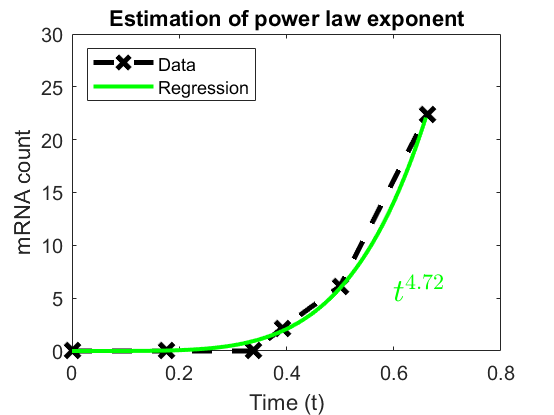


%Compute power law regression curve using estimated prefactor and exponent
time_range2 = 0:0.01:0.66; %time range to compute regression over
reg_Fib_mRNA_Icam1 = prefactor_Fib_mRNA_Icam1.*(time_range2.^exponent_Fib_mRNA_Icam1);

%Plot data and regression results

fig_M = figure;
%data (lines)
p1_M = plot(times_Fib_mRNA_Icam1, mRNAcount_Fib_mRNA_Icam1, 'k--', LineWidth=2.5, Marker="x", MarkerSize=10);
hold on
%regression
p2_M = plot(time_range2, reg_Fib_mRNA_Icam1, '-', 'LineWidth', 2, 'Color', [0,1,0]);
hold on
%data (points)
%s1_M = scatter(times_Fib_mRNA_Icam1, mRNAcount_Fib_mRNA_Icam1, 6, 'x', 'ColorVariable', "#77AC30", 'LineWidth', 10);
%plot features
legend('Data', 'Regression', 'Location', 'northwest')
xlabel('Time (t)')
ylabel('mRNA count')
title('Estimation of power law exponent')
xlim([0, 0.8])
ylim([0, 30])
%add text for exponent
annotation(fig_M,'textbox',...
    [0.691666666666666 0.29536711235484 0.0416666666666668 0.0583613771289075],...
    'Color',[0, 1, 0],...
    'String',{'$t^{4.72}$'},...
    'Interpreter','latex',...
    'FontSize',16,...
    'FitBoxToText','off',...
    'EdgeColor','none');